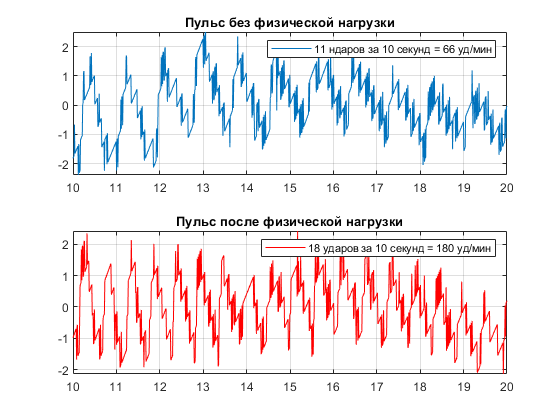

dt = 0.01;

adcBefore = fscanf(fopen('data/data_before.txt'), '%d');
tBefore = linspace(0, length(adcBefore) * dt, length(adcBefore));
pBefore = polyval(c, adcBefore);

adcAfter = fscanf(fopen('data/data_after.txt'), '%d');
tAfter = linspace(0, length(adcAfter) * dt, length(adcAfter));
pAfter = polyval(c, adcAfter);

cBefore = polyfit(tBefore, pBefore, 7);
cAfter = polyfit(tAfter, pAfter, 5);

pulseBefore = pBefore - polyval(cBefore, tBefore)';
pulseAfter = pAfter - polyval(cAfter, tAfter)';

pulseFigure = figure('Name', 'Графики пульса', 'NumberTitle', "off");

subplot(2, 1, 1);
plot(tBefore, pulseBefore);
legend('11 ндаров за 10 секунд = 66 уд/мин');

grid on;
xlim([10, 20]);
title('Пульс без физической нагрузки');

subplot(2, 1, 2);
plot(tAfter, pulseAfter, 'r');
legend('18 ударов за 10 секунд = 180 уд/мин');
title('Пульс после физической нагрузки');

grid on;
xlim([10, 20]);

saveas(pulseFigure, 'Пульс.png')